clear all

close all


Creating the terrain:

dx=6

dx = 6


signal=[];
A=15

A = 15

%fist terrain profile
periods=[50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50]; %randi([min_period,max_period],[1,3])

%seconf profile to be tested
%periods=[60,40, 70, 40, 60,60,40, 70, 40, 60,60,40, 70, 40, 60, 60, 100,40, 40, 40, 50, 60, 70, 40, 50, 60, 100]

%thrid profile to be tested
periods=[30,40,20,40,30,14,20,30,40,20,40,30,13,20,30,40,20,40,30,12,20,30,40,20,40,30,13,20,30,40,20,40,30,13,20,30,40,20,40,30,13,20,30,40,20,40,30,20,20]

periods =     30    40    20    40    30    14    20    30    40    20    40    30    13    20    30    40    20    40    30    12    20    30    40    20    40    30    13    20    30    40    20    40    30    13    20    30    40    20    40    30    13    20    30    40    20    40    30    20    20



%third profile to be tested    change A for A(p) in line 22
%periods=[60,40, 70, 40, 60,60,40, 70, 40, 60,60,40, 70, 40, 60, 60, 100,40, 40, 40, 50, 60, 70, 40, 50, 60, 100]

periods =     60    40    70    40    60    60    40    70    40    60    60    40    70    40    60    60   100    40    40    40    50    60    70    40    50    60   100


%A=[15,5, 15, 15,5, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15]

A =     15     5    15    15     5     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15


for p=1:size(periods,2)
     signal=[signal,step_generator(periods(p), A) ];
end

Unable to perform assignment because the left and right sides have a different number of elements.

Error in step_generator (line 13)
signal(signal == 1) = step1; % set all "1" values to the first step size

%Others to test
%signal=[step_generator(8, 1) , step_generator(4, 0.5), step_generator(6, 1), step_generator(3, 0.5), step_generator(6, 1),step_generator(6, 1)];
%signal=[step_generator(5, 0.5) , step_generator(5, 0.5), step_generator(5, 0.5), step_generator(5, 0.5), step_generator(5, 0.5),step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5)];
signal
d_h_pre=[0];

d_h_post=[0];
for i=2:size(signal,2)-1
    grad=(signal(i)-signal(i-1))/dx;
    d_h_pre=[d_h_pre, grad];
    
    grad=(signal(i+1)-signal(i))/dx;
    d_h_post=[d_h_post, grad];
end

d_h_pre=[d_h_pre,0]
d_h_post=[d_h_post,0]
signal
x=1:dx:(size(signal,2)*dx)
plot(x,signal,"Color", "#9cb27a", 'LineWidth',0.75 )
axis([0 300 -3 15*1.5])
%daspect([2 1 1])
xlabel('Distance (cm)')
ylabel('Height (cm)')
hold on
x=1:dx:(dx*size(signal,2));
scatter(x,d_h_pre,5, 'g')
scatter(x,d_h_post,5, 'b')
% %Generation of the gradient:
hold off



A=[1,0;0,1];
B=[0;1]; 
C=[1;0]

C =      1
     0




nx=2                 % number of states

nx = 2

nu=1                 % number of inputs

nu = 1


% Factors

R=1                  % penalty on control action

R = 1


passa_max=28;
max_grad=1;

Hp=8                        %prediction horizon  

Hp = 8

Hs=Hp*5              %simulation horizon

Hs = 40

N=Hp

N = 8



%Symbolic variable declaration
%u = binvar(repmat(nu,1,Hp),repmat(1,1,Hp));
u=sdpvar(repmat(nu,1,N), ones(1,Hp));


l0=0;

r=[30;1]                  %reference for x -- arribe to L

r =     30
     1



Lhist=[];
Uhist=[];
DHhist_pre=[];
DHhist_post=[];

u_min=0;
u_max=1;
 
steps=0;

for t=1:Hs
% Explicit prediction form
    u = sdpvar(repmat(nu,1,N), ones(1,Hp));
    constraints=[];
    objective=0;
    
    
    l=l0;
 
    for k = 1:Hp
        
        l=(l+dx)*(1-u{k}) %(l+1)*(1-u{k})
        %x = A*x + B*u{k} + C*dx %+0.1*rand(3,1);       %COM
        %objective = objective + (r-x)'*Q*(r-x) + u{k}'*R*u{k};
        objective = objective + u{k}'*R*u{k} ;
        k+steps;
        constraints=[constraints, binary(u{k}), l<=passa_max, -max_grad<=d_h_pre(k+steps)*u{k}<= max_grad, -max_grad<=d_h_post(k+steps)*u{k}<= max_grad];
        %constraints=[constraints, 0<=l<=passa_max, d_h(k+steps)<=max_grad];      %%%   ARREGLAR LA K PQ A CADA PAS ES QUEDA IGUAL!!!
    end
    
    %, u_min<=u{k}<=u_max
    options = sdpsettings('solver','bnb','bnb.solver','fmincon');
    sol=solvesdp(constraints,objective, options) %quadprog va be tmb
    %sol=solvesdp(constraints,objective)
    uu=value(u{:,1})
%     if uu==0.5
%         uu=1
%     end
    %x0=A*x0+B*uu +C*dx %+ 0.05*rand(3,1)
    
    l0=(l0+dx)*(1-uu);
    steps=steps+1;
    DHhist_pre=[DHhist_pre, d_h_pre(steps)];
    DHhist_post=[DHhist_post, d_h_post(steps)];
    
    Lhist = [Lhist l0];
    Uhist = [Uhist uu];
  
  
end

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.000E+00    75.76      1.375E-01   1       0.1    -> Found improved solution! 
    2 :    1.000E+00    75.76      1.375E-01   0       0.2    Successfully solved  
    3 :    1.000E+00    63.18      2.253E-01   1       0.3    Successfully solved  
    4 :    1.000E+00    63.18      2.253E-01   0       0.3    Successfully solved  
    5 :    1.000E+00    33.92      4.932E-01   1       0.4    Successfully solved  
    6 :    1.000E+00    33.92      4.932E-01   0       3.6    Infeasible problem  
    7 :    1.000E+00     0.00      4.932E

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1720
       solvertime: 3.6500
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.000E+00    93.40      1.702E-01   1       0.1    -> Found improved solution! 
    2 :    5.000E+00    93.40      1.702E-01   2       0.1    Successfully solved  
    3 :    5.000E+00    90.03      2.617E-01   3       0.2    Successfully solved  
    4 :    5.000E+00    90.03      2.617E-01   4       0.3    Successfully solved  
    5 :    4.000E+00    76.28      5.379E-01   5       0.3    -> Found improved solution! 
    6 :    4.000E+00    76.28      5.379E-01   4       3.1    Infeasible problem  
    7 :    4.000E+00    59.91     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0940
       solvertime: 6.8730
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.000E+00    93.26      2.089E-01   1       0.1    -> Found improved solution! 
    2 :    6.000E+00    93.26      2.089E-01   2       0.1    Successfully solved  
    3 :    5.000E+00    87.88      3.221E-01   3       0.2    -> Found improved solution! 
    4 :    5.000E+00    87.88      3.221E-01   4       0.3    Successfully solved  
    5 :    5.000E+00    65.97      1.025E+00   3       3.7    Infeasible problem  
    6 :    5.000E+00    65.97      1.025E+00   4       3.8    Successfully solved  
    7 :    3.000E+00    48.39     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0950
       solvertime: 7.4330
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.000E+00    91.47      2.668E-01   1       0.1    -> Found improved solution! 
    2 :    6.000E+00    91.47      2.668E-01   2       0.1    Successfully solved  
    3 :    6.000E+00    70.08      1.055E+00   1       2.2    Infeasible problem  
    4 :    6.000E+00    70.08      1.055E+00   2       2.3    Successfully solved  
    5 :    4.000E+00    57.19      1.089E+00   3       2.4    -> Found improved solution! 
    6 :    4.000E+00    57.19      1.089E+00   4       2.4    Successfully solved  
    7 :    2.000E+00    26.75     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0910
       solvertime: 2.6990
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      8.623E-02   1       0.1    Successfully solved  
    2 :          Inf      Inf      8.623E-02   2       0.2    Successfully solved  
    3 :          Inf      Inf      8.623E-02   3       0.2    Successfully solved  
    4 :          Inf      Inf      8.623E-02   4       0.3    Successfully solved  
    5 :    4.000E+00    95.76      8.623E-02   3       0.3    -> Found improved solution! 
    6 :    4.000E+00    93.56      1.326E-01   4       0.4    Successfully solved  
    7 :    4.000E+00    93.56      1.326

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0950
       solvertime: 0.7950
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.174E-01   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.174E-01   2       0.2    Successfully solved  
    3 :          Inf      Inf      1.174E-01   3       0.2    Successfully solved  
    4 :          Inf      Inf      1.174E-01   4       0.3    Successfully solved  
    5 :          Inf      Inf      1.174E-01   5       0.3    Successfully solved  
    6 :    5.000E+00    95.39      1.174E-01   4       0.4    -> Found improved solution! 
    7 :    4.000E+00    91.73      1.721

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0980
       solvertime: 0.9290
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    96.34      1.485E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    96.34      1.485E-01   2       0.2    Successfully solved  
    3 :    5.000E+00    92.17      2.033E-01   3       0.3    -> Found improved solution! 
    4 :    5.000E+00    92.17      2.033E-01   4       0.4    Successfully solved  
    5 :    5.000E+00    88.60      3.019E-01   5       0.5    Successfully solved  
    6 :    5.000E+00    88.60      3.019E-01   6       0.6    Successfully solved  
    7 :    2.000E+00    61.33    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1130
       solvertime: 2.9930
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    95.53      1.824E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    95.53      1.824E-01   2       0.2    Successfully solved  
    3 :    6.000E+00    92.24      2.417E-01   3       0.3    -> Found improved solution! 
    4 :    6.000E+00    92.24      2.417E-01   4       0.4    Successfully solved  
    5 :    6.000E+00    88.88      3.526E-01   5       0.4    Successfully solved  
    6 :    6.000E+00    88.88      3.526E-01   6       0.5    Successfully solved  
    7 :    5.000E+00    80.50    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1040
       solvertime: 4.2130
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    76.71      1.054E+00   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    76.71      1.054E+00   2       0.2    Successfully solved  
    3 :    4.000E+00    57.29      1.086E+00   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    57.29      1.086E+00   4       0.3    Successfully solved  
    5 :    2.000E+00    27.04      1.148E+00   1       0.3    -> Found improved solution! 
    6 :    2.000E+00    27.04      1.148E+00   0       0.4    Successfully solved  
    7 :    2.000E+00    21

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0930
       solvertime: 0.6880
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.000E+00    91.66      1.301E-01   1       0.1    -> Found improved solution! 
    2 :    3.000E+00    91.66      1.301E-01   2       0.1    Successfully solved  
    3 :    2.000E+00    80.75      2.125E-01   3       0.2    -> Found improved solution! 
    4 :    2.000E+00    80.75      2.125E-01   4       0.2    Successfully solved  
    5 :    1.000E+00    45.70      3.724E-01   1       0.3    -> Found improved solution! 
    6 :    1.000E+00    45.70      3.724E-01   2       0.4    Successfully solved  
    7 :    1.000E+00    19

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0970
       solvertime: 3.7250
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    87.43      2.678E-01   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    87.43      2.678E-01   2       0.1    Successfully solved  
    3 :    2.000E+00    63.69      4.433E-01   3       0.2    -> Found improved solution! 
    4 :    1.000E+00    38.54      4.433E-01   2       0.3    -> Found improved solution! 
    5 :    1.000E+00    15.41      7.328E-01   1       0.3    Successfully solved  
    6 :    1.000E+00    15.41      7.328E-01   0       3.4    Infeasible problem  
    7 :    1.000E+00     0.

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0860
       solvertime: 3.4560
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.000E+00    88.60      3.019E-01   1       0.1    -> Found improved solution! 
    2 :    5.000E+00    88.60      3.019E-01   2       0.1    Successfully solved  
    3 :    2.000E+00    61.33      4.790E-01   3       0.2    -> Found improved solution! 
    4 :    2.000E+00    61.33      4.790E-01   4       0.3    Successfully solved  
    5 :    2.000E+00    44.58      7.664E-01   5       0.3    Successfully solved  
    6 :    2.000E+00    44.58      7.664E-01   6       0.4    Successfully solved  
    7 :    2.000E+00    33.22    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0890
       solvertime: 9.0260
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.000E+00    89.24      3.406E-01   1       0.1    -> Found improved solution! 
    2 :    6.000E+00    89.24      3.406E-01   2       0.1    Successfully solved  
    3 :    5.000E+00    81.08      5.220E-01   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    76.90      5.220E-01   4       0.3    -> Found improved solution! 
    5 :    4.000E+00    66.54      8.034E-01   5       0.3    Successfully solved  
    6 :    2.000E+00    42.67      8.034E-01   6       0.4    -> Found improved solution! 
    7 :    2.000E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0970
       solvertime: 5.3100
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    58.03      1.062E+00   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    58.03      1.062E+00   2       0.1    Successfully solved  
    3 :    3.000E+00    46.11      1.106E+00   3       0.2    -> Found improved solution! 
    4 :    3.000E+00    46.11      1.106E+00   4       0.2    Successfully solved  
    5 :    2.000E+00    24.78      1.205E+00   1       0.3    -> Found improved solution! 
    6 :    2.000E+00    24.78      1.205E+00   0       0.3    Successfully solved  
    7 :    2.000E+00     0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0980
       solvertime: 2.1650
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    95.43      9.313E-02   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    95.43      9.313E-02   2       0.1    Successfully solved  
    3 :    3.000E+00    90.70      1.458E-01   3       0.2    -> Found improved solution! 
    4 :    3.000E+00    90.70      1.458E-01   4       0.3    Successfully solved  
    5 :    2.000E+00    77.95      2.474E-01   5       0.3    -> Found improved solution! 
    6 :    2.000E+00    77.95      2.474E-01   6       0.4    Successfully solved  
    7 :    1.000E+00    39

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0920
       solvertime: 0.5370
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    91.25      1.826E-01   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    91.25      1.826E-01   2       0.1    Successfully solved  
    3 :    3.000E+00    82.30      2.908E-01   3       0.2    -> Found improved solution! 
    4 :    3.000E+00    82.30      2.908E-01   4       0.3    Successfully solved  
    5 :    2.000E+00    61.37      4.784E-01   5       0.4    -> Found improved solution! 
    6 :    1.000E+00    35.26      4.784E-01   2       0.5    -> Found improved solution! 
    7 :    1.000E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1000
       solvertime: 0.5820
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    84.63      3.325E-01   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    84.63      3.325E-01   2       0.1    Successfully solved  
    3 :    3.000E+00    70.28      5.231E-01   3       0.2    -> Found improved solution! 
    4 :    3.000E+00    70.28      5.231E-01   4       0.3    Successfully solved  
    5 :    3.000E+00    58.62      7.823E-01   5       0.3    Successfully solved  
    6 :    3.000E+00    58.62      7.823E-01   4       0.4    Infeasible problem  
    7 :    3.000E+00    49.82     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1020
       solvertime: 0.6990
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.000E+00    86.42      3.636E-01   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    83.31      3.636E-01   2       0.1    -> Found improved solution! 
    3 :    4.000E+00    75.64      5.543E-01   3       0.2    Successfully solved  
    4 :    4.000E+00    75.64      5.543E-01   4       0.3    Successfully solved  
    5 :    3.000E+00    57.32      8.134E-01   5       0.3    -> Found improved solution! 
    6 :    3.000E+00    57.32      8.134E-01   6       0.4    Successfully solved  
    7 :    3.000E+00    48

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0970
       solvertime: 5.5710
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.071E+00   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.071E+00   2       0.1    Successfully solved  
    3 :          Inf      Inf      1.071E+00   3       0.2    Successfully solved  
    4 :    4.000E+00    57.76      1.071E+00   2       0.2    -> Found improved solution! 
    5 :    3.000E+00    45.24      1.131E+00   2       0.3    -> Found improved solution! 
    6 :    3.000E+00    45.24      1.131E+00   3       0.4    Successfully solved  
    7 :    2.000E+00    11.54    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0910
       solvertime: 2.6020
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.018E-01   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.018E-01   2       0.2    Successfully solved  
    3 :          Inf      Inf      1.018E-01   3       0.2    Successfully solved  
    4 :    3.000E+00    93.40      1.018E-01   2       0.3    -> Found improved solution! 
    5 :    3.000E+00    89.74      1.618E-01   3       0.3    Successfully solved  
    6 :    3.000E+00    89.74      1.618E-01   4       0.4    Successfully solved  
    7 :    3.000E+00    65.86      6.171

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0920
       solvertime: 11.4280
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.335E-01   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.335E-01   2       0.2    Successfully solved  
    3 :          Inf      Inf      1.335E-01   3       0.2    Successfully solved  
    4 :    3.000E+00    91.45      1.335E-01   2       0.3    -> Found improved solution! 
    5 :    3.000E+00    87.82      1.940E-01   3       0.3    Successfully solved  
    6 :    3.000E+00    87.82      1.940E-01   4       0.4    Successfully solved  
    7 :    3.000E+00    64.29      6.517

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1140
       solvertime: 13.3860
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.000E+00    91.27      2.276E-01   1       0.1    -> Found improved solution! 
    2 :    5.000E+00    91.27      2.276E-01   2       0.1    Successfully solved  
    3 :    4.000E+00    84.02      3.469E-01   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    84.02      3.469E-01   4       0.3    Successfully solved  
    5 :    3.000E+00    69.46      5.403E-01   5       0.3    -> Found improved solution! 
    6 :    2.000E+00    57.44      5.403E-01   6       0.4    -> Found improved solution! 
    7 :    2.000E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0980
       solvertime: 7.5190
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.000E+00    80.34      2.176E-01   1       0.1    -> Found improved solution! 
    2 :    2.000E+00    80.34      2.176E-01   2       0.1    Successfully solved  
    3 :    1.000E+00    44.70      3.818E-01   1       0.2    -> Found improved solution! 
    4 :    1.000E+00    44.70      3.818E-01   2       0.3    Successfully solved  
    5 :    1.000E+00    18.92      6.816E-01   1       0.3    Successfully solved  
    6 :    1.000E+00    18.92      6.816E-01   0       0.3    Infeasible problem  
    7 :    1.000E+00     0.00     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0970
       solvertime: 0.3600
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.000E+00    77.84      2.488E-01   1       0.1    -> Found improved solution! 
    2 :    2.000E+00    77.84      2.488E-01   2       0.2    Successfully solved  
    3 :    1.000E+00    41.52      4.130E-01   1       0.2    -> Found improved solution! 
    4 :    1.000E+00    41.52      4.130E-01   2       0.3    Successfully solved  
    5 :    1.000E+00    16.76      7.128E-01   1       0.3    Successfully solved  
    6 :    1.000E+00    16.76      7.128E-01   0       3.8    Infeasible problem  
    7 :    1.000E+00     0.00     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0930
       solvertime: 3.7930
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.000E+00    75.41      2.799E-01   1       0.1    -> Found improved solution! 
    2 :    2.000E+00    75.41      2.799E-01   2       0.1    Successfully solved  
    3 :    2.000E+00    63.63      4.441E-01   3       0.2    Successfully solved  
    4 :    2.000E+00    63.63      4.441E-01   4       0.3    Successfully solved  
    5 :    2.000E+00    45.76      7.439E-01   5       0.4    Successfully solved  
    6 :    2.000E+00    45.76      7.439E-01   4       3.8    Infeasible problem  
    7 :    2.000E+00    33.22      1.002E

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1000
       solvertime: 11.1750
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.000E+00    82.55      3.819E-01   1       0.1    -> Found improved solution! 
    2 :    4.000E+00    82.55      3.819E-01   2       0.1    Successfully solved  
    3 :    2.000E+00    56.49      5.557E-01   3       0.2    -> Found improved solution! 
    4 :    2.000E+00    56.49      5.557E-01   4       0.2    Successfully solved  
    5 :    2.000E+00    40.46      8.474E-01   5       0.3    Successfully solved  
    6 :    2.000E+00    40.46      8.474E-01   6       0.3    Successfully solved  
    7 :    2.000E+00    34.45    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0940
       solvertime: 5.8210
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.000E+00    26.14      1.171E+00   1       0.1    -> Found improved solution! 
    2 :    2.000E+00    26.14      1.171E+00   0       0.1    Successfully solved  
    3 :    2.000E+00    19.88      1.337E+00   1       0.1    Successfully solved  
    4 :    2.000E+00    19.88      1.337E+00   0       0.2    Infeasible problem  
    5 :    2.000E+00     0.00      1.337E+00   0       0.3    Successfully solved  
+   5 Finishing.  Cost: 2


sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0940
       solvertime: 0.2650
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.000E+00    66.32      2.021E-01   1       0.1    -> Found improved solution! 
    2 :    1.000E+00    66.32      2.021E-01   0       0.1    Successfully solved  
    3 :    1.000E+00    46.20      3.677E-01   1       0.1    Successfully solved  
    4 :    1.000E+00    46.20      3.677E-01   0       2.7    Infeasible problem  
    5 :    1.000E+00     0.00      3.677E-01   0       2.8    Successfully solved  
+   5 Finishing.  Cost: 1


sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0930
       solvertime: 2.7800
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.000E+00    61.88      2.351E-01   1       0.1    -> Found improved solution! 
    2 :    1.000E+00    61.88      2.351E-01   0       0.1    Successfully solved  
    3 :    1.000E+00    42.57      4.026E-01   1       0.2    Successfully solved  
    4 :    1.000E+00    42.57      4.026E-01   0       3.6    Infeasible problem  
    5 :    1.000E+00     0.00      4.026E-01   0       3.6    Successfully solved  
+   5 Finishing.  Cost: 1


sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0990
       solvertime: 3.5970
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.000E+00    89.87      2.663E-01   1       0.1    -> Found improved solution! 
    2 :    5.000E+00    89.87      2.663E-01   2       0.1    Successfully solved  
    3 :    4.000E+00    80.42      4.337E-01   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    80.42      4.337E-01   2       3.4    Infeasible problem  
    5 :    4.000E+00    59.91      1.002E+00   3       3.5    Successfully solved  
    6 :    2.000E+00    33.22      1.002E+00   2       3.5    -> Found improved solution! 
    7 :    2.000E+00    33.

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1110
       solvertime: 5.8870
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.000E+00    90.54      2.974E-01   1       0.1    -> Found improved solution! 
    2 :    6.000E+00    90.54      2.974E-01   2       0.1    Successfully solved  
    3 :    5.000E+00    82.97      4.648E-01   3       0.2    -> Found improved solution! 
    4 :    5.000E+00    82.97      4.648E-01   2       3.6    Infeasible problem  
    5 :    5.000E+00    65.97      1.025E+00   3       3.7    Successfully solved  
    6 :    5.000E+00    65.97      1.025E+00   4       3.7    Successfully solved  
    7 :    3.000E+00    48.39     

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0930
       solvertime: 7.2940
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.055E+00   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.055E+00   2       0.2    Successfully solved  
    3 :          Inf      Inf      1.055E+00   3       0.2    Successfully solved  
    4 :    4.000E+00    58.24      1.055E+00   2       0.3    -> Found improved solution! 
    5 :    4.000E+00    57.19      1.089E+00   3       0.3    Successfully solved  
    6 :    4.000E+00    57.19      1.089E+00   4       0.4    Successfully solved  
    7 :    2.000E+00    26.75      1.156

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1110
       solvertime: 0.5930
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      8.623E-02   1       0.1    Successfully solved  
    2 :          Inf      Inf      8.623E-02   2       0.1    Successfully solved  
    3 :          Inf      Inf      8.623E-02   3       0.2    Successfully solved  
    4 :          Inf      Inf      8.623E-02   4       0.3    Successfully solved  
    5 :    4.000E+00    95.76      8.623E-02   3       0.3    -> Found improved solution! 
    6 :    4.000E+00    93.56      1.326E-01   4       0.4    Successfully solved  
    7 :    4.000E+00    93.56      1.326

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0900
       solvertime: 0.7500
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :          Inf      Inf      1.174E-01   1       0.1    Successfully solved  
    2 :          Inf      Inf      1.174E-01   2       0.1    Successfully solved  
    3 :          Inf      Inf      1.174E-01   3       0.2    Successfully solved  
    4 :          Inf      Inf      1.174E-01   4       0.2    Successfully solved  
    5 :          Inf      Inf      1.174E-01   5       0.3    Successfully solved  
    6 :    5.000E+00    95.39      1.174E-01   4       0.3    -> Found improved solution! 
    7 :    4.000E+00    91.73      1.721

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0930
       solvertime: 0.8770
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    96.34      1.485E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    96.34      1.485E-01   2       0.1    Successfully solved  
    3 :    5.000E+00    92.17      2.033E-01   3       0.2    -> Found improved solution! 
    4 :    5.000E+00    92.17      2.033E-01   4       0.3    Successfully solved  
    5 :    5.000E+00    88.60      3.019E-01   5       0.4    Successfully solved  
    6 :    5.000E+00    88.60      3.019E-01   6       0.4    Successfully solved  
    7 :    2.000E+00    61.33    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1100
       solvertime: 2.7010
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24
Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30
Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36
Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42
Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48
Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54
Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60
Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    95.53      1.824E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    95.53      1.824E-01   2       0.1    Successfully solved  
    3 :    6.000E+00    92.24      2.417E-01   3       0.2    -> Found improved solution! 
    4 :    6.000E+00    92.24      2.417E-01   4       0.3    Successfully solved  
    5 :    6.000E+00    88.88      3.526E-01   5       0.4    Successfully solved  
    6 :    6.000E+00    88.88      3.526E-01   6       0.5    Successfully solved  
    7 :    5.000E+00    80.50    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.0970
       solvertime: 4.0100
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30
Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36
Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42
Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48
Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54
Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60
Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66
Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    76.71      1.054E+00   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    76.71      1.054E+00   2       0.1    Successfully solved  
    3 :    4.000E+00    57.29      1.086E+00   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    57.29      1.086E+00   4       0.3    Successfully solved  
    5 :    2.000E+00    27.04      1.148E+00   1       0.3    -> Found improved solution! 
    6 :    2.000E+00    27.04      1.148E+00   0       0.4    Successfully solved  
    7 :    2.000E+00    21

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1010
       solvertime: 0.6330
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6
Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12
Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18
Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24
Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30
Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36
Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42
Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    97.89      8.489E-02   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    97.89      8.489E-02   2       0.2    Successfully solved  
    3 :    3.000E+00    91.66      1.301E-01   3       0.3    -> Found improved solution! 
    4 :    3.000E+00    91.66      1.301E-01   4       0.3    Successfully solved  
    5 :    2.000E+00    80.75      2.125E-01   5       0.4    -> Found improved solution! 
    6 :    2.000E+00    80.75      2.125E-01   6       0.4    Successfully solved  
    7 :    1.000E+00    45

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1490
       solvertime: 0.7890
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12
Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18
Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24
Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30
Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36
Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42
Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48
Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    97.12      1.163E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    97.12      1.163E-01   2       0.1    Successfully solved  
    3 :    4.000E+00    91.80      1.705E-01   3       0.2    -> Found improved solution! 
    4 :    4.000E+00    91.80      1.705E-01   4       0.3    Successfully solved  
    5 :    4.000E+00    87.43      2.678E-01   5       0.3    Successfully solved  
    6 :    4.000E+00    87.43      2.678E-01   6       0.4    Successfully solved  
    7 :    2.000E+00    63.69    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1050
       solvertime: 0.6860
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18
Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24
Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30
Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36
Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42
Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48
Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54
Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    8.000E+00    96.34      1.485E-01   1       0.1    -> Found improved solution! 
    2 :    8.000E+00    96.34      1.485E-01   2       0.2    Successfully solved  
    3 :    5.000E+00    92.17      2.033E-01   3       0.2    -> Found improved solution! 
    4 :    5.000E+00    92.17      2.033E-01   4       0.3    Successfully solved  
    5 :    5.000E+00    88.60      3.019E-01   5       0.4    Successfully solved  
    6 :    5.000E+00    88.60      3.019E-01   6       0.4    Successfully solved  
    7 :    2.000E+00    61.33    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1150
       solvertime: 2.6640
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

%plot



passos=[]


passos =

     []



prev=0

prev = 0

z_pas=8

z_pas = 8


for i=1:length(Uhist)
    if Uhist(i)==1
        i;
        mig=fix((i-prev)/2+prev);
        passos=[passos;prev*dx, mig*dx, i*dx ];
        prev=i;
    end
end
passos

passos =      0    12    24
    24    36    54
    54    66    84
    84    96   114
   114   120   132
   132   144   162
   162   174   192
   192   204   222


passos=passos

passos =      0    12    24
    24    36    54
    54    66    84
    84    96   114
   114   120   132
   132   144   162
   162   174   192
   192   204   222


%x_signal=1:dx:length(signal)*dx
%signal
%plot(x_signal ,signal,'Color', "#9cb27a", 'LineWidth',0.75 )
%signal to plot
hpy=[]


hpy =

     []



count=1

count = 1

prev=signal(1)

prev = 15

for i =1:length(signal)
    hpy=[hpy, signal(i)*ones(1,6)]; 
end
x_signal=1:1:length(hpy)

x_signal =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


hpy

hpy =     15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot(x_signal ,hpy,'Color', "#9cb27a", 'LineWidth',0.75 )
axis([0 Hs*dx+5 0 25])
hold on
colors=["#ffc9de ","#fdd97c " , "#b2e4f0 ", "#d6b2f0 "];
color=1;
%primer pas
syms a b c
x_p = [passos(1,1),passos(1,2),passos(1,3)]

x_p =      0    12    24


h_max=max(signal(1), signal(fix(passos(1,3))))

h_max = 15

if h_max ==0
    h_max=z_pas;
end
y_p = [signal(fix(1)), h_max*1.5, signal(fix(passos(1,3))/6)]

y_p =    15.0000   22.5000   15.0000


eqn = y_p == a*x_p.^2+b*x_p+c;

sol = solve(eqn,[a b c]);
a_s=double(sol.a);
b_s=double(sol.b);
c_s=double(sol.c);

x_pp=passos(1,1):dx:passos(1,3)

x_pp =      0     6    12    18    24


y_pp=x_pp.^2*a_s+x_pp.*b_s+c_s

y_pp =    15.0000   20.6250   22.5000   20.6250   15.0000


colors(color)

ans = "#ffc9de "

plot(x_pp,y_pp, 'Color', colors(color), 'LineWidth',1)
title("Simulation with variable periods and gradients")
xlabel('Distance (cm)')
ylabel('Height (cm)')
color=color+1

color = 2


for i=2:length(passos)
    syms a b c
    x_p = [passos(i,1),passos(i,2),passos(i,3)]
    h_max=max(signal(fix(passos(i,1)/dx)), signal(fix(passos(i,3)/dx)))
    if h_max == 0
        h_max=z_pas;
    end
    y_p = [signal(fix(passos(i,1)/dx)), h_max*1.3, signal(fix(passos(i,3)/dx))]
    eqn = y_p == a*x_p.^2+b*x_p+c;
 
    sol = solve(eqn,[a b c]);
    a_s=double(sol.a);
    b_s=double(sol.b);
    c_s=double(sol.c);

    x_pp=passos(i,1):dx:passos(i,3);
    y_pp=x_pp.^2*a_s+x_pp.*b_s+c_s;
    colors(color)
    plot(x_pp,y_pp, 'Color', colors(color), 'LineWidth',1)
    color=color+1
    if color== length(colors)
        color=1;
    end
    
end

x_p =     24    36    54


h_max = 15

y_p =    15.0000   19.5000         0


ans = "#fdd97c "

color = 3

x_p =     54    66    84


h_max = 5

y_p =          0    6.5000    5.0000


ans = "#b2e4f0 "

color = 4

x_p =     84    96   114


h_max = 15

y_p =     5.0000   19.5000   15.0000


ans = "#ffc9de "

color = 2

x_p =    114   120   132


h_max = 15

y_p =    15.0000   19.5000   15.0000


ans = "#fdd97c "

color = 3

x_p =    132   144   162


h_max = 15

y_p =    15.0000   19.5000         0


ans = "#b2e4f0 "

color = 4

x_p =    162   174   192


h_max = 15

y_p =          0   19.5000   15.0000


ans = "#ffc9de "

color = 2

x_p =    192   204   222


h_max = 15

y_p =    15.0000   19.5000    5.0000


ans = "#fdd97c "

color = 3

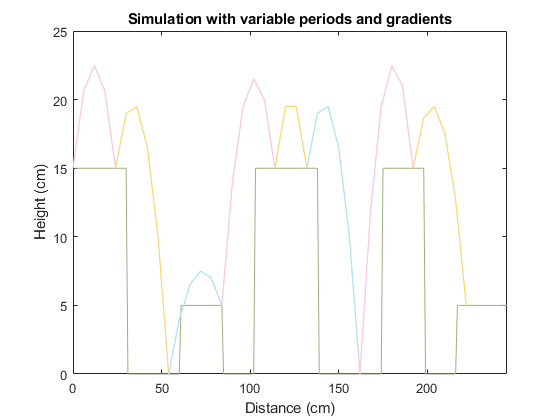



hold off